# Plots for report

clear all;

## Search for We and Wu to give optimal setteling time

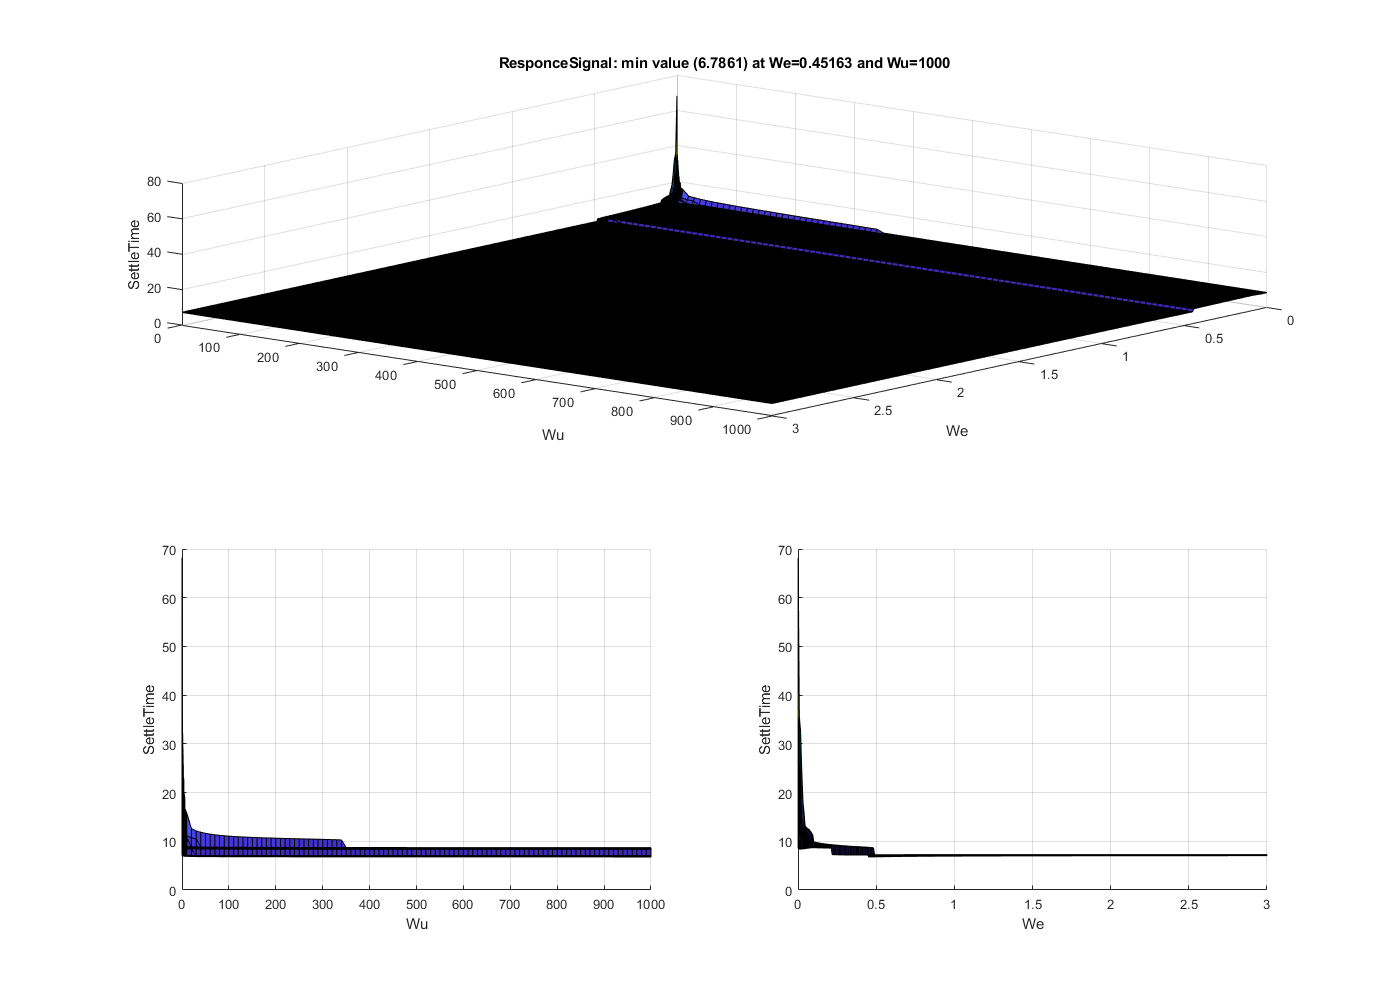

ans =   Figure (4: ResponceSignal) with properties:

      Number: 4
        Name: 'ResponceSignal'
       Color: [1 1 1]
    Position: [300 100 1400 1000]
       Units: 'pixels'

  Show all properties


We_Wu_grid = load('dataLogging_We_Wu_grid.mat');
% score(plant_number,We,Wu)
plot_cutoff_search(We_Wu_grid.score_l_h(1,:,:),...
    'x_array',We_Wu_grid.We_array,'x_label','We',...
    'y_array',We_Wu_grid.Wu_array,'y_label','Wu',...
    'z_label','SettleTime')

## Plot Step Responces

### load data

plants = load('plants.mat');
controllers = load('Controllers.mat');

### With Perfect Plant

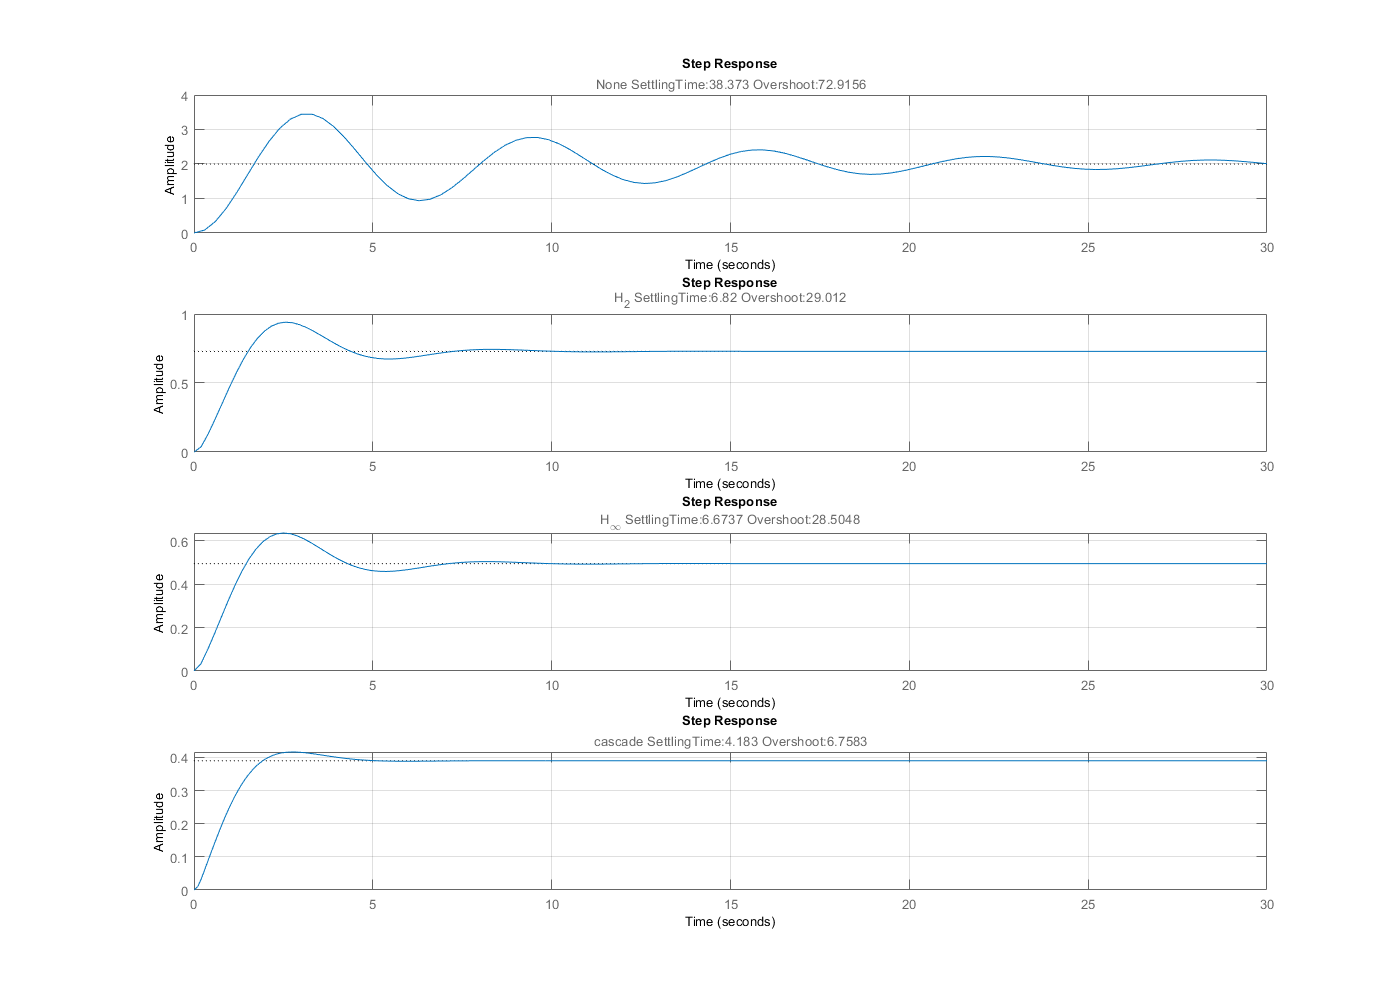

plot_step_responce(controllers,plants,...
    'plant',{'plant_aug','plant_aug','plant_aug','plant_CL_LQR'},...
    'controller',{'controller_none','controller_H2','controller_Hinf','controller_cascade'},...
    'feedback',[1,1,1,1],...
    'title',{'None','H_2','H_\infty','Cascade'},...
    'FigureTitle','StepResponcePerfect_Robust')

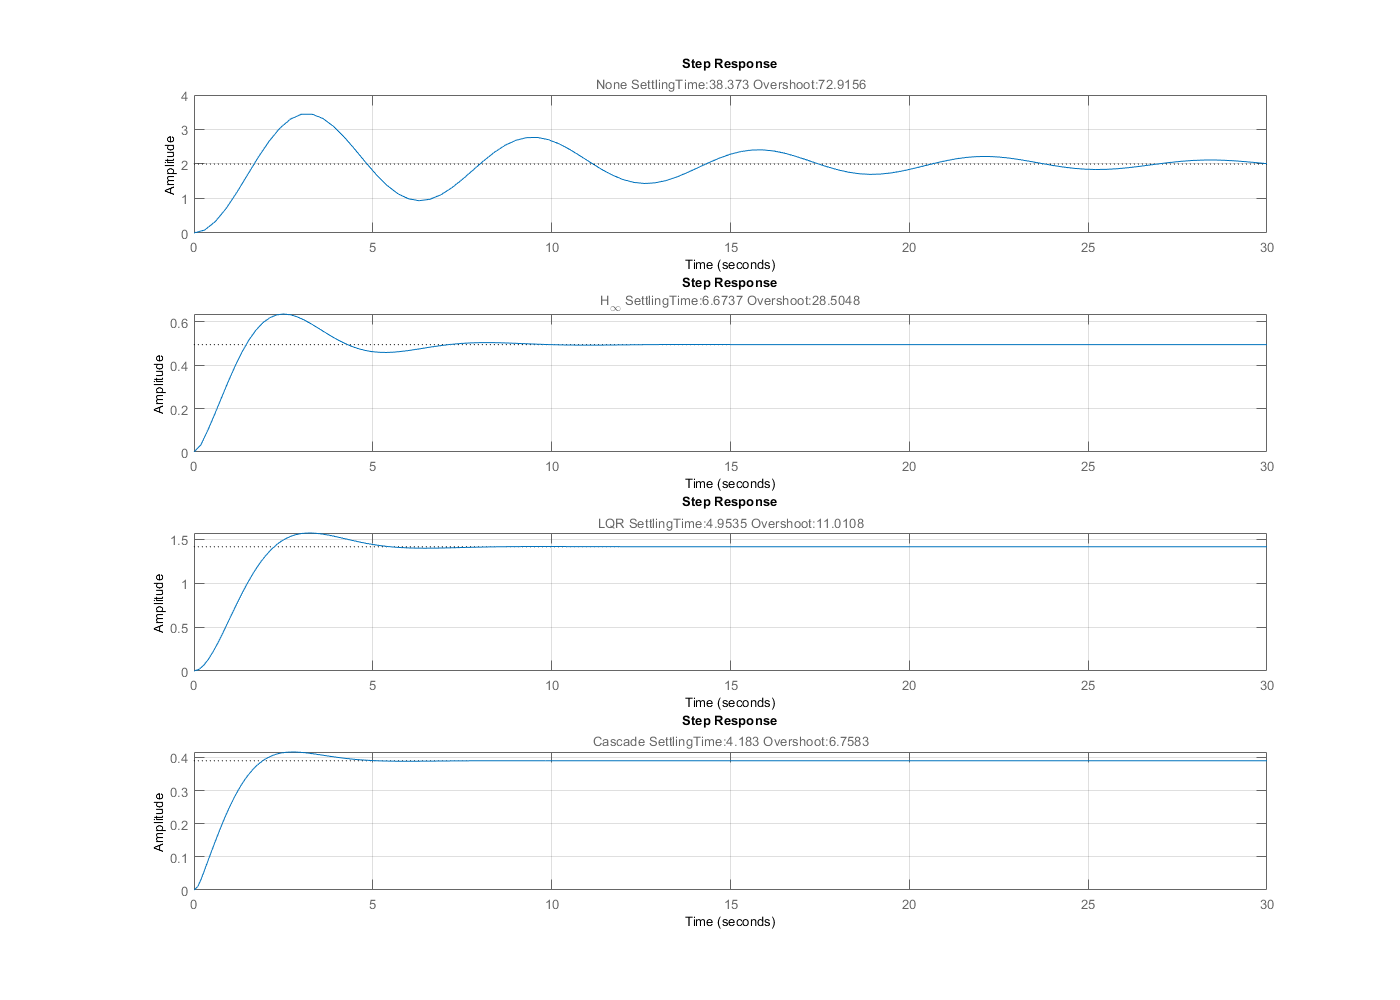


plot_step_responce(controllers,plants,...
    'plant',{'plant_aug','plant_aug','plant_aug','plant_CL_LQR'},...
    'controller',{'controller_none','controller_Hinf','controller_LQR','controller_cascade'},...
    'feedback',[-1,1,-1,1],...
    'title',{'None','H_\infty','LQR','Cascade'},...
    'FigureTitle','StepResponcePerfect_Paper')

### With Plant Errors

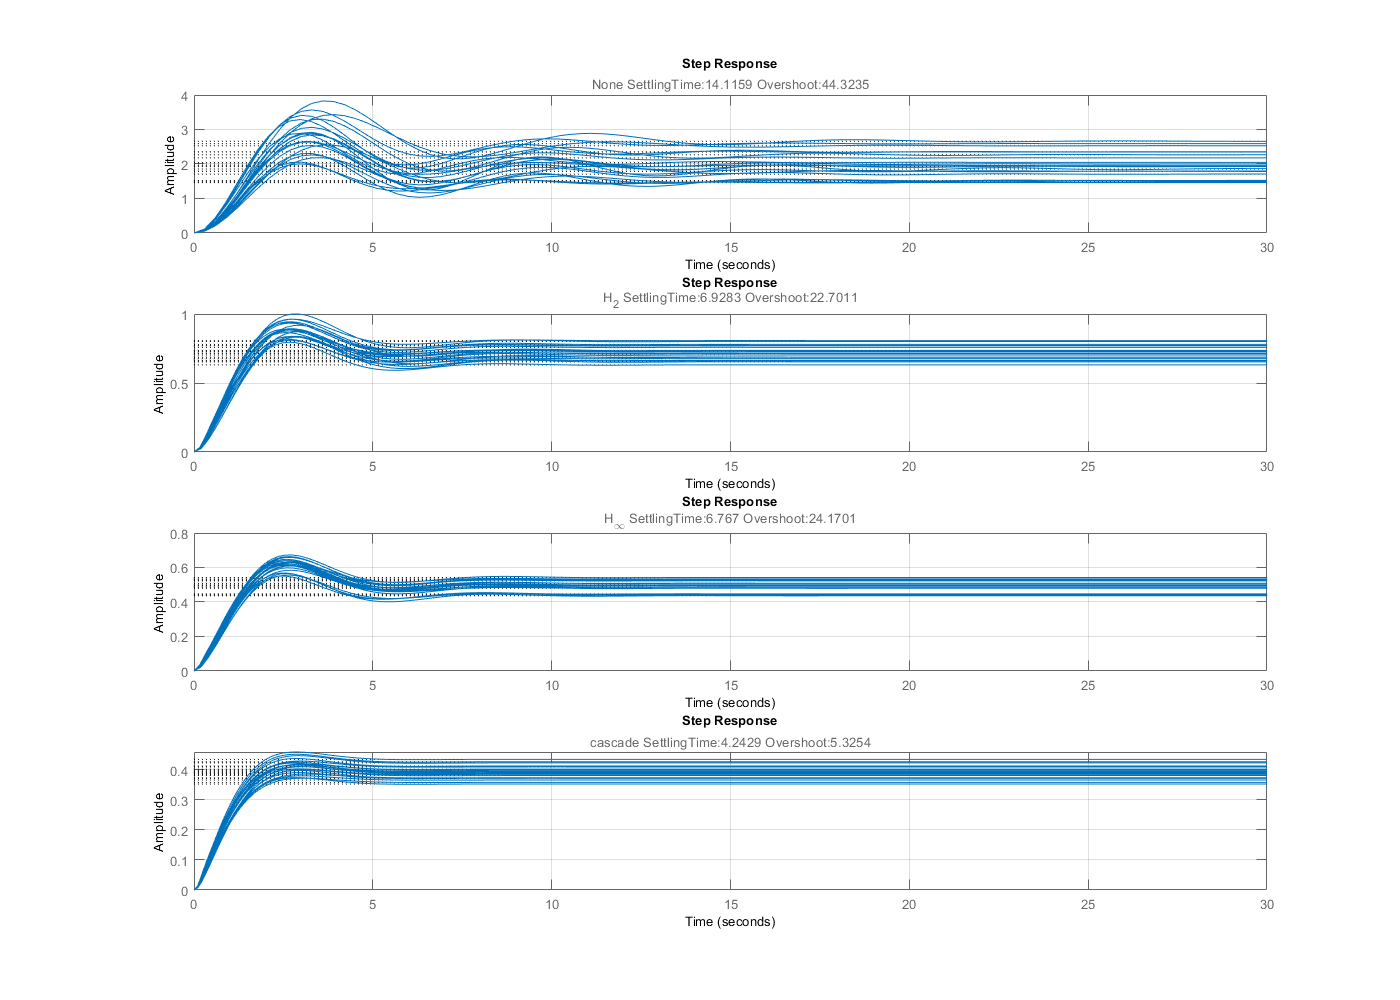

plot_step_responce(controllers,plants,...
    'plant',{'plant_aug_u','plant_aug_u','plant_aug_u','plant_CL_LQR_u'},...
    'controller',{'controller_none','controller_H2','controller_Hinf','controller_cascade'},...
    'feedback',[1,1,1,1],...
    'title',{'None','H_2','H_\infty','Cascade'},...
    'FigureTitle','StepResponceNoise_Robust')

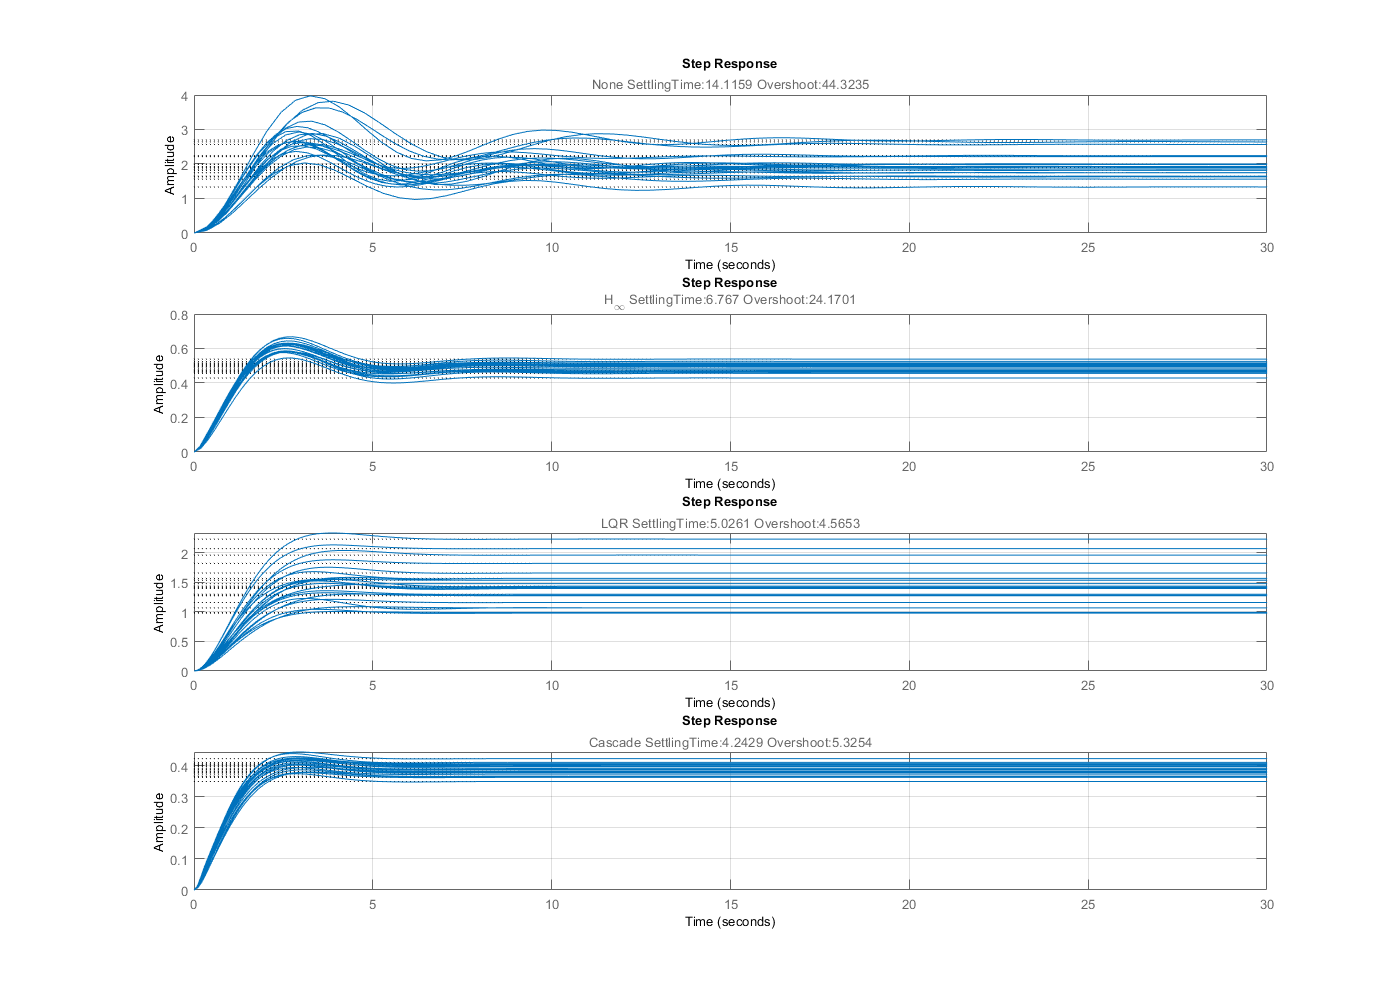


plot_step_responce(controllers,plants,...
    'plant',{'plant_aug_u','plant_aug_u','plant_aug_u','plant_CL_LQR_u'},...
    'controller',{'controller_none','controller_Hinf','controller_LQR','controller_cascade'},...
    'feedback',[-1,1,-1,1],...
    'title',{'None','H_\infty','LQR','Cascade'},...
    'FigureTitle','StepResponceNoise_Paper')